# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');
warning('off','all')

Since we deal with a discrete-time implementation of controllers, we need to specify the sampling time. For this reason we select a choice of T on wich we are going to test our controllers.

T = [0.001 0.01 0.05];

## 2.1 Design by emulation

The discretization problem consists of finding a discrete-time controller C(z) such that the input–output transfer function of the sampled–data controller, approximates (in some sense) the transfer function C0(s).

### **2.1.1 Position PID Controller**

Discrete PID design

% Config
simul.Ts_selector = 2;
simul.disc_select = 2; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
simul.stepdeg = 360;
simul.FFW = 1;

%pidz.Kw = 5/perf.ts5;
pidz.Kw = 13.33;
pidz.Kw = 0;

% Define transfer function
s = tf('s');
Ts = T(simul.Ts_selector);
z = tf('z',Ts);
Pdelay = exp(-s*Ts/2)*(paramP.km/(gbox.N*s*(paramP.Tm*s+1)));

% Get magnitue and phase at the desired frequency
[magPwg, phasePwg] = bode(Pdelay, perf.wg);
dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

% Estimation of the paramters of the PID-discrete time controller (system with time delay)
a = 4000; % TUNE                     % First attempt 4000
pidz.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;
pidz.T_l = 1/(2*perf.wg);

pidz.Kd = pidz.K*Td;
pidz.Ki = pidz.K/Ti;

s_forward = (z-1)/Ts;
s_backward = (z-1)/(Ts*z);

pidz.C = pidz.K + pidz.Ki*(1/s) + pidz.Kd * (s/(T_l*s + 1)); % CT model

pidz.Cb = pidz.K + pidz.Ki*(1/s_backward) + pidz.Kd * (s_backward/(T_l*s_backward + 1)); % backward disc
pidz.Cf = pidz.K + pidz.Ki*(1/s_forward) + pidz.Kd * (s_forward/(T_l*s_forward + 1)); % forward disc
pidz.Ctust = c2d(pidz.C,Ts,'tustin'); % tustin disc
pidz.Czoh = c2d(pidz.C,Ts,'zoh'); % 'exact' disc

pidz.controllers = [pidz.Cf, pidz.Cb, pidz.Ctust, pidz.Czoh];

% Get data of implemented controller
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');

% zpk(pidz.Cb)
% zpk(pidz.Cf)

### **2.1.2 Position State-Space Controller**

Reconsider the position state–space controller for nominal and robust perfect tracking of constant set–points designed in the second laboratory activity. Differently from the second laboratory activity, suppose that the plant state is not fully accessible, so that a state observer is required to get an estimate of all the unmeasurable state variables.

**Reduced order state observer (CT)**

redObs.L = 10;
redObs.A0 = -(1/paramP.Tm + redObs.L);
redObs.B0 = [paramP.km/(gbox.N*paramP.Tm), -(1/paramP.Tm + redObs.L)*redObs.L];
redObs.C0 = [0; 1];
redObs.D0 = [0 1; 0 redObs.L];

**CT Test - Nominal tracking**

simul.stepdeg = 40;
nominal_track.CT.deg_40 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Program interruption (Ctrl-C) has been detected.

simul.stepdeg = 70;
nominal_track.CT.deg_70 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
nominal_track.CT.deg_120 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

In this figure we check the tracking of the reference and the difference between the real and the estimated speed

figure
subplot(2,3,1);
hold on;
plot(nominal_track.CT.deg_40.thref.time, nominal_track.CT.deg_40.thref.signals.values,'--');
plot(nominal_track.CT.deg_40.thl_meas.time, nominal_track.CT.deg_40.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(nominal_track.CT.deg_70.thref.time, nominal_track.CT.deg_70.thref.signals.values,'--');
plot(nominal_track.CT.deg_70.thl_meas.time, nominal_track.CT.deg_70.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(nominal_track.CT.deg_120.thref.time, nominal_track.CT.deg_120.thref.signals.values,'--');
plot(nominal_track.CT.deg_120.thl_meas.time, nominal_track.CT.deg_120.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(nominal_track.CT.deg_40.wl_meas.time, nominal_track.CT.deg_40.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_40.wl_est.time, nominal_track.CT.deg_40.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.CT.deg_70.wl_meas.time, nominal_track.CT.deg_70.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_70.wl_est.time, nominal_track.CT.deg_70.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.CT.deg_120.wl_meas.time, nominal_track.CT.deg_120.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_120.wl_est.time, nominal_track.CT.deg_120.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Forwar Euler discretization**

We can repeat the same procedure also for other discretization methods. Pay attention to the simulation time T!! We perform the test of the controller using different sampling times

simul.stepdeg = 50;
simul.Ts_selector = 1;

Simulation for 1 ms

redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T1 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','8', 'AlgebraicLoopMsg', 'off');

Simulation for 10 ms

simul.Ts_selector = 2;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T2 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','8', 'AlgebraicLoopMsg', 'off');

Simulation for 50 ms

simul.Ts_selector = 3;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T3 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','8', 'AlgebraicLoopMsg', 'off');

figure
subplot(2,3,1);
hold on;
plot(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--');
plot(nominal_track.FE.T1.thl_est.time, nominal_track.FE.T1.thl_meas.signals.values);
plot(nominal_track.FE.T1.thl_meas.time, nominal_track.FE.T1.thl_meas.signals.values);
legend('Reference', 'Estimated', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(nominal_track.FE.T2.thref.time, nominal_track.FE.T2.thref.signals.values,'--');
plot(nominal_track.FE.T2.thl_est.time, nominal_track.FE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(nominal_track.FE.T3.thref.time, nominal_track.FE.T3.thref.signals.values,'--');
plot(nominal_track.FE.T3.thl_est.time, nominal_track.FE.T3.thl_meas.signals.values);
legend('Reference', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(nominal_track.FE.T1.wl_meas.time, nominal_track.FE.T1.wl_meas.signals.values,'--');
plot(nominal_track.FE.T1.wl_est.time, nominal_track.FE.T1.wl_est.signals.values);
legend('Measured', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.FE.T2.wl_meas.time, nominal_track.FE.T2.wl_meas.signals.values,'--');
plot(nominal_track.FE.T2.wl_est.time, nominal_track.FE.T2.wl_est.signals.values);
legend('Measured', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.FE.T3.wl_meas.time, nominal_track.FE.T3.wl_meas.signals.values,'--');
plot(nominal_track.FE.T3.wl_est.time, nominal_track.FE.T3.wl_est.signals.values);
legend('Measured', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Backward Euler discretization**

simul.stepdeg = 50;

Simulation for 1 ms

simul.Ts_selector = 1;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = inv(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0*inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0*inv(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);

nominal_track.BE.T1 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 10 ms

simul.Ts_selector = 2;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = inv(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0*inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0*inv(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);

nominal_track.BE.T2 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 50 ms

simul.Ts_selector = 3;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = inv(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0*inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0*inv(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);

nominal_track.BE.T3 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

figure
subplot(2,3,1);
hold on;
plot(nominal_track.BE.T1.thref.time, nominal_track.BE.T1.thref.signals.values,'--');
plot(nominal_track.BE.T1.thl_meas.time, nominal_track.BE.T1.thl_meas.signals.values);
legend('ReBErence', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(nominal_track.BE.T2.thref.time, nominal_track.BE.T2.thref.signals.values,'--');
plot(nominal_track.BE.T2.thl_meas.time, nominal_track.BE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(nominal_track.BE.T3.thref.time, nominal_track.BE.T3.thref.signals.values,'--');
plot(nominal_track.BE.T3.thl_meas.time, nominal_track.BE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(nominal_track.BE.T1.wl_meas.time, nominal_track.BE.T1.wl_meas.signals.values,'--');
plot(nominal_track.BE.T1.wl_est.time, nominal_track.BE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.BE.T2.wl_meas.time, nominal_track.BE.T2.wl_meas.signals.values,'--');
plot(nominal_track.BE.T2.wl_est.time, nominal_track.BE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.BE.T3.wl_meas.time, nominal_track.BE.T3.wl_meas.signals.values,'--');
plot(nominal_track.BE.T3.wl_est.time, nominal_track.BE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

save('NominalTrack.mat','nominal_track');

Reduced order state observer (CT) for** robust traking**

redObs.L = 0.1;
redObs.A0 = -(1/paramP.Tm + redObs.L);
redObs.B0 = [paramP.km/(gbox.N*paramP.Tm), -(1/paramP.Tm + redObs.L)*redObs.L];
redObs.C0 = [0; 1];
redObs.D0 = [0 1; 0 redObs.L];

**CT - Robust tracking**

We have already implemeted the observer. we have just to put in the model and to test it

simul.stepdeg = 40;
robust_track.CT.deg_40 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
simul.stepdeg = 70;
robust_track.CT.deg_70 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
robust_track.CT.deg_120 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

In this figure we check the tracking of the reference and the difference between the real and the estimated speed

figure
subplot(2,3,1);
hold on;
plot(robust_track.CT.deg_40.thref.time, robust_track.CT.deg_40.thref.signals.values,'--');
plot(robust_track.CT.deg_40.thl_meas.time, robust_track.CT.deg_40.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(robust_track.CT.deg_70.thref.time, robust_track.CT.deg_70.thref.signals.values,'--');
plot(robust_track.CT.deg_70.thl_meas.time, robust_track.CT.deg_70.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(robust_track.CT.deg_120.thref.time, robust_track.CT.deg_120.thref.signals.values,'--');
plot(robust_track.CT.deg_120.thl_meas.time, robust_track.CT.deg_120.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')

subplot(2,3,4)
hold on;
plot(robust_track.CT.deg_40.wl_meas.time, robust_track.CT.deg_40.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_40.wl_est.time, robust_track.CT.deg_40.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

subplot(2,3,5)
hold on;
plot(robust_track.CT.deg_70.wl_meas.time, robust_track.CT.deg_70.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_70.wl_est.time, robust_track.CT.deg_70.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

subplot(2,3,6)
hold on;
plot(robust_track.CT.deg_120.wl_meas.time, robust_track.CT.deg_120.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_120.wl_est.time, robust_track.CT.deg_120.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Forwar Euler discretization**

At each simulation we choice a different simulation time. This tije must be set in the discrete integrator, in all the 'zoh' blocks.

simul.stepdeg = 50;

Simulation for 1 ms

simul.Ts_selector = 1;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T1 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 10 ms

simul.Ts_selector = 2;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T2 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

Simulation for 50 ms

simul.Ts_selector = 3;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T3 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

figure
subplot(2,3,1);
hold on;
plot(robust_track.FE.T1.thref.time, robust_track.FE.T1.thref.signals.values,'--');
plot(robust_track.FE.T1.thl_meas.time, robust_track.FE.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [1ms]')

subplot(2,3,2);
hold on;
plot(robust_track.FE.T2.thref.time, robust_track.FE.T2.thref.signals.values,'--');
plot(robust_track.FE.T2.thl_meas.time, robust_track.FE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [10ms]')

subplot(2,3,3);
hold on;
plot(robust_track.FE.T3.thref.time, robust_track.FE.T3.thref.signals.values,'--');
plot(robust_track.FE.T3.thl_meas.time, robust_track.FE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [50ms]')
subplot(2,3,4)
hold on;
plot(robust_track.FE.T1.wl_meas.time, robust_track.FE.T1.wl_meas.signals.values,'--');
plot(robust_track.FE.T1.wl_est.time, robust_track.FE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(robust_track.FE.T2.wl_meas.time, robust_track.FE.T2.wl_meas.signals.values,'--');
plot(robust_track.FE.T2.wl_est.time, robust_track.FE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(robust_track.FE.T3.wl_meas.time, robust_track.FE.T3.wl_meas.signals.values,'--');
plot(robust_track.FE.T3.wl_est.time, robust_track.FE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Backward Euler discretization**

ssP.SysCT = ss(ssP.A,ssP.B,ssP.C,ssP.D);


**Tustin discretization**

We observe that the matrix D has nonzero entries, and this causes an algbraic loop.

ssP.SysTU = c2d(ssP.SysCT,Ts,'tustin');
display(ssP.SysTU)

## **2.2 **Direct digital desing

The direct design in the discrete–time domain can be performed with any of the available classical or modern design methods, after having obtained a discrete–time model of the plant to be controlled with the exact discretization method.

#### Discretization of the model

Discretise the continuous–time state–space model Σ = (A, B, C, D) of the DC gearmotor using the exact method, to obtain the “ZOH discrete equivalent” Σd = (Φ, Γ, H, J). Note that since D = 0, then also J = 0. This condition will be considered throughout all this section.The discretization can be performed by using the c2d routine of the Control System Toolbox (CST), making sure to specify ’zoh’ as the discretization method.

% define continous time ssm
ssNominalDT.SysCT = ss(ssP.A,ssP.B,ssP.C,ssP.D); 
%reference remains constant during the simulations
simul.stepdeg = 50;

#### **Nominal Tracking**

Design a discrete–time position state–space controller for nominal perfect tracking of constant position set–points, using the discretised plant model Σd obtained in point 1.Since the motor speed is not directly measurable, consider to design a discrete–time reduced– order observer for estimating it. The speed estimate, together with the motor position provided by the encoder, will be used to perform the state feedback.

Simulation for 1 ms

the discrete time state space must be modified for each sample time

simul.Ts_selector = 1;
% creating discrete ssm
ssNominalDT.SysD = c2d(ssNominalDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssNominalDT.redObs.L = 10;
ssNominalDT.redObs.Ph0 = ssNominalDT.SysD.A(2,2) - ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,2);
ssNominalDT.redObs.Gamma0 = [ssNominalDT.SysD.B(2)-ssNominalDT.redObs.L*ssNominalDT.SysD.B(1) ssNominalDT.redObs.Ph0*ssNominalDT.redObs.L+ssNominalDT.SysD.A(2,1)-ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,1)];
ssNominalDT.redObs.C0 = [0; 1];
ssNominalDT.redObs.D0 = [0 1; 0 ssNominalDT.redObs.L];

% CHECK ALL THIS PART
ssNominalDT.N = [ssNominalDT.SysD.A - eye(2) ssNominalDT.SysD.B; ssNominalDT.SysD.C ssNominalDT.SysD.D]\[zeros(2,1); 1];
ssNominalDT.Nx = ssNominal.N(1:2);
ssNominalDT.Nu = ssNominal.N(3);

ssNominal.poles = [-perf.d*perf.wn+1i*perf.wn*sqrt(1-perf.d^2), -perf.d*perf.wn-1i*perf.wn*sqrt(1-perf.d^2)];
% old poles --> must be transformed
ssNominalDT.poles = exp(ssNominal.poles*T(simul.Ts_selector));
ssNominalDT.K = place(ssNominalDT.SysD.A, ssNominalDT.SysD.B, ssNominalDT.poles);

ss_direct_nominal.T1 = sim('ss_nominal_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_nominal.T1.ssNominalDT = ssNominalDT;

Simulation for 10 ms

simul.Ts_selector = 2;
% creating discrete ssm
ssNominalDT.SysD = c2d(ssNominalDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssNominalDT.redObs.L = 10;
ssNominalDT.redObs.Ph0 = ssNominalDT.SysD.A(2,2) - ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,2);
ssNominalDT.redObs.Gamma0 = [ssNominalDT.SysD.B(2)-ssNominalDT.redObs.L*ssNominalDT.SysD.B(1) ssNominalDT.redObs.Ph0*ssNominalDT.redObs.L+ssNominalDT.SysD.A(2,1)-ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,1)];
ssNominalDT.redObs.C0 = [0; 1];
ssNominalDT.redObs.D0 = [0 1; 0 ssNominalDT.redObs.L];

ssNominalDT.N = [ssNominalDT.SysD.A - eye(2) ssNominalDT.SysD.B; ssNominalDT.SysD.C ssNominalDT.SysD.D]\[zeros(2,1); 1];
ssNominalDT.Nx = ssNominal.N(1:2);
ssNominalDT.Nu = ssNominal.N(3);
%ssNominal.poles = [-10+5*1i, -10-5*1i];
ssNominal.poles = [-perf.d*perf.wn+1i*perf.wn*sqrt(1-perf.d^2), -perf.d*perf.wn-1i*perf.wn*sqrt(1-perf.d^2)];
% old poles --> must be transformed
ssNominalDT.poles = exp(ssNominal.poles*T(simul.Ts_selector));
ssNominalDT.K = place(ssNominalDT.SysD.A, ssNominalDT.SysD.B, ssNominalDT.poles);

ss_direct_nominal.T2 = sim('ss_nominal_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_nominal.T2.ssNominalDT = ssNominalDT;

Simulation for 50 ms

simul.Ts_selector = 3;
% creating discrete ssm
ssNominalDT.SysD = c2d(ssNominalDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssNominalDT.redObs.L = 10;
ssNominalDT.redObs.Ph0 = ssNominalDT.SysD.A(2,2) - ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,2);
ssNominalDT.redObs.Gamma0 = [ssNominalDT.SysD.B(2)-ssNominalDT.redObs.L*ssNominalDT.SysD.B(1) ssNominalDT.redObs.Ph0*ssNominalDT.redObs.L+ssNominalDT.SysD.A(2,1)-ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,1)];
ssNominalDT.redObs.C0 = [0; 1];
ssNominalDT.redObs.D0 = [0 1; 0 ssNominalDT.redObs.L];

% CHECK ALL THIS PART
ssNominalDT.N = [ssNominalDT.SysD.A - eye(2) ssNominalDT.SysD.B; ssNominalDT.SysD.C ssNominalDT.SysD.D]\[zeros(2,1); 1];
ssNominalDT.Nx = ssNominal.N(1:2);
ssNominalDT.Nu = ssNominal.N(3);

ssNominal.poles = [-perf.d*perf.wn+1i*perf.wn*sqrt(1-perf.d^2), -perf.d*perf.wn-1i*perf.wn*sqrt(1-perf.d^2)];
% old poles --> must be transformed
ssNominalDT.poles = exp(ssNominal.poles*T(simul.Ts_selector));
ssNominalDT.K = place(ssNominalDT.SysD.A, ssNominalDT.SysD.B, ssNominalDT.poles);

ss_direct_nominal.T3 = sim('ss_nominal_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_nominal.T3.ssNominalDT = ssNominalDT;

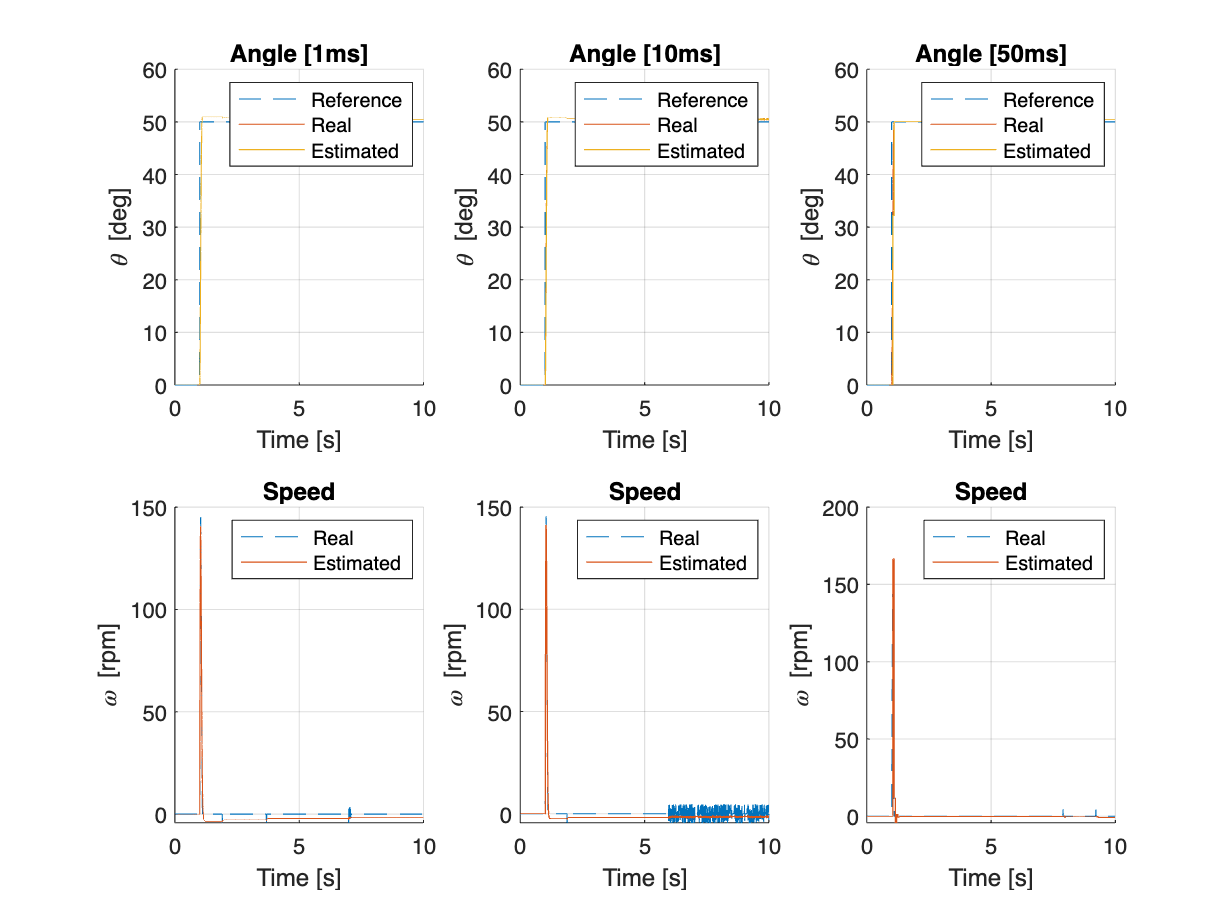

figure
subplot(2,3,1);
hold on;
plot(ss_direct_nominal.T1.thref.time, ss_direct_nominal.T1.thref.signals.values,'--');
plot(ss_direct_nominal.T1.thl_meas.time, ss_direct_nominal.T1.thl_meas.signals.values);
plot(ss_direct_nominal.T1.thl_est.time, ss_direct_nominal.T1.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [1ms]')

subplot(2,3,2);
hold on;
plot(ss_direct_nominal.T2.thref.time, ss_direct_nominal.T2.thref.signals.values,'--');
plot(ss_direct_nominal.T2.thl_meas.time, ss_direct_nominal.T2.thl_meas.signals.values);
plot(ss_direct_nominal.T2.thl_est.time, ss_direct_nominal.T2.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [10ms]')

subplot(2,3,3);
hold on;
plot(ss_direct_nominal.T3.thref.time, ss_direct_nominal.T3.thref.signals.values,'--');
plot(ss_direct_nominal.T3.thl_meas.time, ss_direct_nominal.T3.thl_meas.signals.values);
plot(ss_direct_nominal.T3.thl_est.time, ss_direct_nominal.T3.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [50ms]')
subplot(2,3,4)
hold on;
plot(ss_direct_nominal.T1.wl_meas.time, ss_direct_nominal.T1.wl_meas.signals.values,'--');
plot(ss_direct_nominal.T1.wl_est.time, ss_direct_nominal.T1.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(ss_direct_nominal.T2.wl_meas.time, ss_direct_nominal.T2.wl_meas.signals.values,'--');
plot(ss_direct_nominal.T2.wl_est.time, ss_direct_nominal.T2.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(ss_direct_nominal.T3.wl_meas.time, ss_direct_nominal.T3.wl_meas.signals.values,'--');
plot(ss_direct_nominal.T3.wl_est.time, ss_direct_nominal.T3.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

#### **Robust perfect tracking**

Design a discrete–time position state–space controller with integral action to achieve robust perfect tracking of constant position set–points, and perfect rejection of constant turbances. For the design, use the discretised plant model Σd obtained in point discrete–time reduced–order observer similar to that obtained in point 2.

% define continous time ssm
ssRobustDT.SysCT = ss(ssP.A,ssP.B,ssP.C,ssP.D); 
%reference remains constant during the simulations
simul.stepdeg = 50;

Simulation for 1 ms

the discrete time state space must be modified for each sample time

simul.Ts_selector = 1;
% creating discrete ssm
ssRobustDT.SysD = c2d(ssRobustDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssRobustDT.redObs.L = 10;
ssRobustDT.redObs.Ph0 = ssRobustDT.SysD.A(2,2) - ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,2);
ssRobustDT.redObs.Gamma0 = [ssRobustDT.SysD.B(2)-ssRobustDT.redObs.L*ssRobustDT.SysD.B(1) ssRobustDT.redObs.Ph0*ssRobustDT.redObs.L+ssRobustDT.SysD.A(2,1)-ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,1)];
ssRobustDT.redObs.C0 = [0; 1];
ssRobustDT.redObs.D0 = [0 1; 0 ssRobustDT.redObs.L];

ssRobustDT.N = [ssRobustDT.SysD.A - eye(2) ssRobustDT.SysD.B; ssRobustDT.SysD.C ssRobustDT.SysD.D]\[zeros(2,1); 1];
ssRobustDT.Nx = ssNominal.N(1:2);
ssRobustDT.Nu = ssNominal.N(3);

ssRobustDT.Phe = [1 ssRobustDT.SysD.C ;zeros(2, 1) ssRobustDT.SysD.A];
ssRobustDT.Gammae =[0; ssRobustDT.SysD.B];

ssRobust.poles = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -2*perf.sigmamin];

% old poles --> must be transformed
ssRobustDT.poles = exp(ssRobust.poles*T(simul.Ts_selector));

ssRobustDT.Ke = place(ssRobustDT.Phe, ssRobustDT.Gammae, ssRobustDT.poles);
ssRobustDT.K = ssRobustDT.Ke(2:3);
ssRobustDT.Ki = ssRobustDT.Ke(1);

ss_direct_robust.T1 = sim('ss_robust_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_robust.T1.ssRobustDT = ssRobustDT;

Simulation for 10 ms

simul.Ts_selector = 2;
% creating discrete ssm
ssRobustDT.SysD = c2d(ssRobustDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssRobustDT.redObs.L = 10;
ssRobustDT.redObs.Ph0 = ssRobustDT.SysD.A(2,2) - ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,2);
ssRobustDT.redObs.Gamma0 = [ssRobustDT.SysD.B(2)-ssRobustDT.redObs.L*ssRobustDT.SysD.B(1) ssRobustDT.redObs.Ph0*ssRobustDT.redObs.L+ssRobustDT.SysD.A(2,1)-ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,1)];
ssRobustDT.redObs.C0 = [0; 1];
ssRobustDT.redObs.D0 = [0 1; 0 ssRobustDT.redObs.L];

ssRobustDT.N = [ssRobustDT.SysD.A - eye(2) ssRobustDT.SysD.B; ssRobustDT.SysD.C ssRobustDT.SysD.D]\[zeros(2,1); 1];
ssRobustDT.Nx = ssNominal.N(1:2);
ssRobustDT.Nu = ssNominal.N(3);

ssRobustDT.Phe = [1 ssRobustDT.SysD.C ;zeros(2, 1) ssRobustDT.SysD.A];
ssRobustDT.Gammae =[0; ssRobustDT.SysD.B];

ssRobust.poles = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -2*perf.sigmamin];

% old poles --> must be transformed
ssRobustDT.poles = exp(ssRobust.poles*T(simul.Ts_selector));

ssRobustDT.Ke = place(ssRobustDT.Phe, ssRobustDT.Gammae, ssRobustDT.poles);
ssRobustDT.K = ssRobustDT.Ke(2:3);
ssRobustDT.Ki = ssRobustDT.Ke(1);

ss_direct_robust.T2 = sim('ss_robust_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_robust.T2.ssRobustDT = ssRobustDT;

Simulation for 50 ms

simul.Ts_selector = 3;
% creating discrete ssm
ssRobustDT.SysD = c2d(ssRobustDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssRobustDT.redObs.L = 10;
ssRobustDT.redObs.Ph0 = ssRobustDT.SysD.A(2,2) - ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,2);
ssRobustDT.redObs.Gamma0 = [ssRobustDT.SysD.B(2)-ssRobustDT.redObs.L*ssRobustDT.SysD.B(1) ssRobustDT.redObs.Ph0*ssRobustDT.redObs.L+ssRobustDT.SysD.A(2,1)-ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,1)];
ssRobustDT.redObs.C0 = [0; 1];
ssRobustDT.redObs.D0 = [0 1; 0 ssRobustDT.redObs.L];

ssRobustDT.N = [ssRobustDT.SysD.A - eye(2) ssRobustDT.SysD.B; ssRobustDT.SysD.C ssRobustDT.SysD.D]\[zeros(2,1); 1];
ssRobustDT.Nx = ssNominal.N(1:2);
ssRobustDT.Nu = ssNominal.N(3);

ssRobustDT.Phe = [1 ssRobustDT.SysD.C ;zeros(2, 1) ssRobustDT.SysD.A];
ssRobustDT.Gammae =[0; ssRobustDT.SysD.B];

ssRobust.poles = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -2*perf.sigmamin];

% old poles --> must be transformed
ssRobustDT.poles = exp(ssRobust.poles*T(simul.Ts_selector));

ssRobustDT.Ke = place(ssRobustDT.Phe, ssRobustDT.Gammae, ssRobustDT.poles);
ssRobustDT.K = ssRobustDT.Ke(2:3);
ssRobustDT.Ki = ssRobustDT.Ke(1);

ss_direct_robust.T3 = sim('ss_robust_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_robust.T3.ssRobustDT = ssRobustDT;

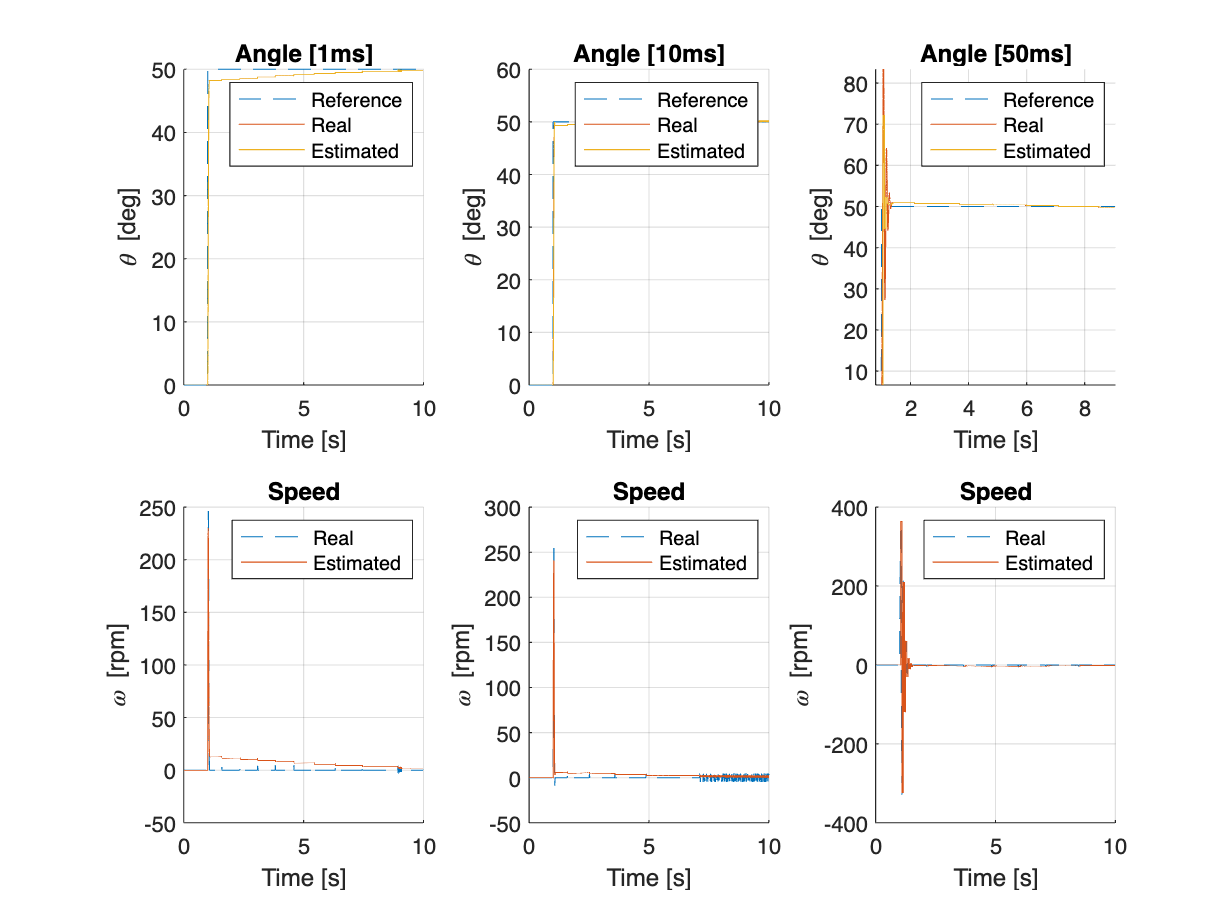

figure
subplot(2,3,1);
hold on;
plot(ss_direct_robust.T1.thref.time, ss_direct_robust.T1.thref.signals.values,'--');
plot(ss_direct_robust.T1.thl_meas.time, ss_direct_robust.T1.thl_meas.signals.values);
plot(ss_direct_robust.T1.thl_est.time, ss_direct_robust.T1.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [1ms]')

subplot(2,3,2);
hold on;
plot(ss_direct_robust.T2.thref.time, ss_direct_robust.T2.thref.signals.values,'--');
plot(ss_direct_robust.T2.thl_meas.time, ss_direct_robust.T2.thl_meas.signals.values);
plot(ss_direct_robust.T2.thl_est.time, ss_direct_robust.T2.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [10ms]')

subplot(2,3,3);
hold on;
plot(ss_direct_robust.T3.thref.time, ss_direct_robust.T3.thref.signals.values,'--');
plot(ss_direct_robust.T3.thl_meas.time, ss_direct_robust.T3.thl_meas.signals.values);
plot(ss_direct_robust.T3.thl_est.time, ss_direct_robust.T3.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [50ms]')

subplot(2,3,4)
hold on;
plot(ss_direct_robust.T1.wl_meas.time, ss_direct_robust.T1.wl_meas.signals.values,'--');
plot(ss_direct_robust.T1.wl_est.time, ss_direct_robust.T1.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;

plot(ss_direct_robust.T2.wl_meas.time, ss_direct_robust.T2.wl_meas.signals.values,'--');
plot(ss_direct_robust.T2.wl_est.time, ss_direct_robust.T2.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(ss_direct_robust.T3.wl_meas.time, ss_direct_robust.T3.wl_meas.signals.values,'--');
plot(ss_direct_robust.T3.wl_est.time, ss_direct_robust.T3.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')